# Fourier series

*© *Copyright 2022 The MathWorks, Inc

syms x n
assume (n, ["integer" "positive"])
L = 1;

f(x) = piecewise(x<L/2, x, x >=L/2, x-L /2); % define sawtooth function

clear b
b(n) = simplify(2/L* int(f(x) * sin(n*pi/L * x), 0, L)) % Fourier coefficients

$$b(n) = -\frac{{\left(-1\right)}^{n/2}\,{\left({\left(-1\right)}^{n/2}+1\right)}^{2}}{2\,n\,\pi }$$

b(1:10) % display the first 10 coeff

$$ans = \left(\begin{array}{cccccccccc} \frac{1}{\pi } & 0 & \frac{1}{3\,\pi } & -\frac{1}{2\,\pi } & \frac{1}{5\,\pi } & 0 & \frac{1}{7\,\pi } & -\frac{1}{4\,\pi } & \frac{1}{9\,\pi } & 0 \end{array}\right)$$

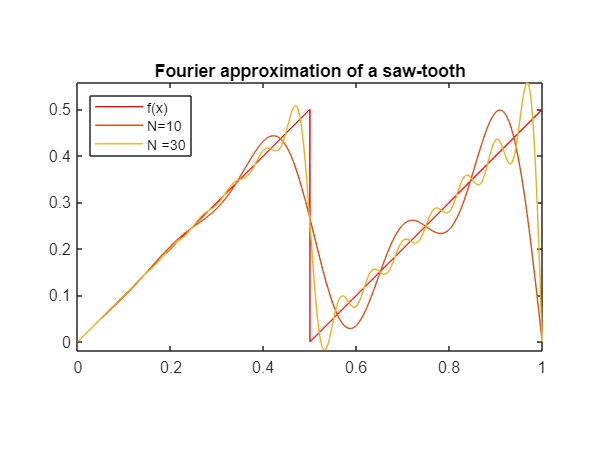


fplot (f, [0 L], "r")
axis equal 
hold on
for N = [10 30]
    f_approx = symsum(b(n) * sin(n*pi/L*x), n, 1, N); % symbolic sum of N terms
    fplot(f_approx , [0 L]);
end
legend ({'f(x)', 'N=10 ', 'N =30 '}, "Location","northwest")
title ('Fourier approximation of a saw-tooth')

**Animation for the sawtooth function:**

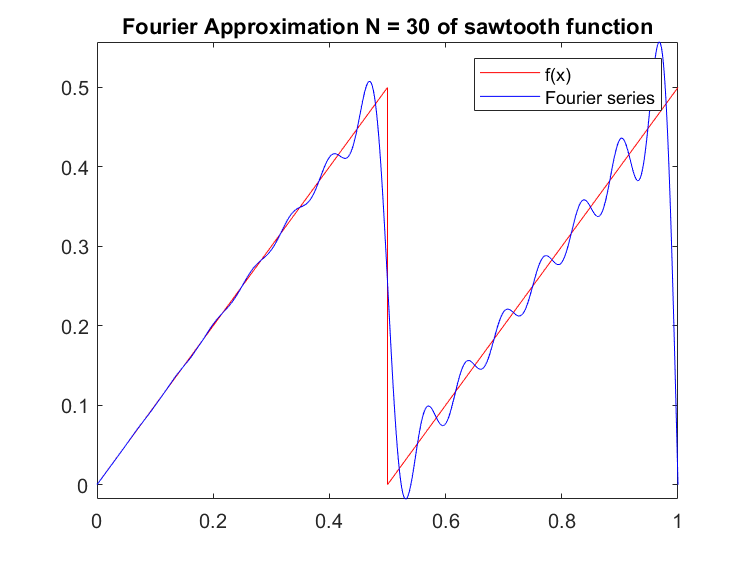

N = 30;
figure, 
fplot(f, [0 L], "r"), hold on
for k = 1:N
    phi_approx = symsum(b(n) * sin(n*pi/L*x), n, 1, k);
    h = fplot(phi_approx, [0 L], "b");
    title("Fourier Approximation N = " + k + " of sawtooth function")
    drawnow
    if k<N, delete(h), end
 end
legend("f(x)", "Fourier series")

**Try with another function: a square wave**

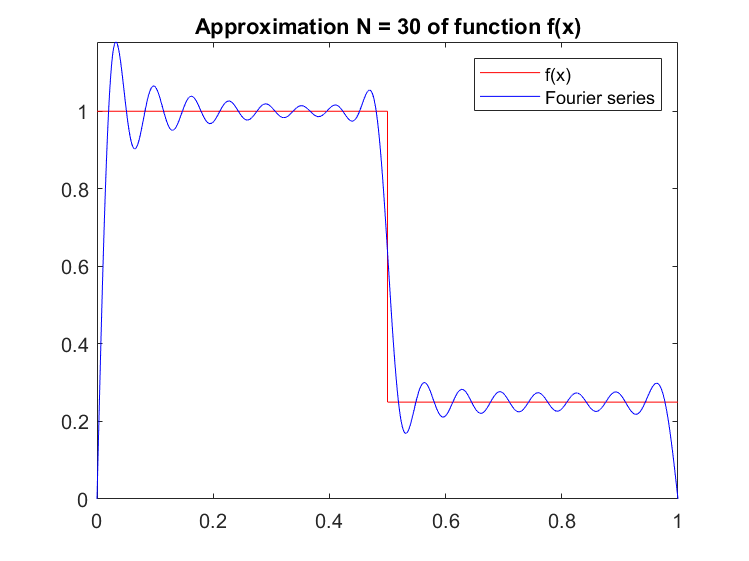

$$f\_approx = \frac{5\,\sin\left(\pi \,x\right)}{2\,\pi }+\frac{3\,\sin\left(2\,\pi \,x\right)}{2\,\pi }+\frac{5\,\sin\left(3\,\pi \,x\right)}{6\,\pi }+\frac{\sin\left(5\,\pi \,x\right)}{2\,\pi }+\frac{\sin\left(6\,\pi \,x\right)}{2\,\pi }+\frac{5\,\sin\left(7\,\pi \,x\right)}{14\,\pi }+\frac{5\,\sin\left(9\,\pi \,x\right)}{18\,\pi }+\frac{3\,\sin\left(10\,\pi \,x\right)}{10\,\pi }+\frac{5\,\sin\left(11\,\pi \,x\right)}{22\,\pi }+\frac{5\,\sin\left(13\,\pi \,x\right)}{26\,\pi }+\frac{3\,\sin\left(14\,\pi \,x\right)}{14\,\pi }+\frac{\sin\left(15\,\pi \,x\right)}{6\,\pi }+\frac{5\,\sin\left(17\,\pi \,x\right)}{34\,\pi }+\frac{\sin\left(18\,\pi \,x\right)}{6\,\pi }+\frac{5\,\sin\left(19\,\pi \,x\right)}{38\,\pi }+\frac{5\,\sin\left(21\,\pi \,x\right)}{42\,\pi }+\frac{3\,\sin\left(22\,\pi \,x\right)}{22\,\pi }+\frac{5\,\sin\left(23\,\pi \,x\right)}{46\,\pi }+\frac{\sin\left(25\,\pi \,x\right)}{10\,\pi }+\frac{3\,\sin\left(26\,\pi \,x\right)}{26\,\pi }+\frac{5\,\sin\left(27\,\pi \,x\right)}{54\,\pi }+\frac{5\,\sin\left(29\,\pi \,x\right)}{58\,\pi }+\frac{\sin\left(30\,\pi \,x\right)}{10\,\pi }$$

$$b(n) = \frac{7\,{\sin\left(\frac{\pi \,n}{4}\right)}^{2}-4\,{\sin\left(\frac{\pi \,n}{4}\right)}^{4}}{n\,\pi }$$

L = 1; 
N = 30;
f(x) =  piecewise(x<L/2, L, x> L/2, L/4);  % with jump
[f_approx, b] = fourier_approx(f, L, N)

function [phi_approx, b] = fourier_approx(phi, L, N)
syms n b(n) x
assume(n, ["integer" "positive"])
b(n) = simplify(2/L* int(phi(x) * sin(n*pi/L * x), 0, L));

figure 
fplot(phi, [0 L], "r")
hold on
for k = 1:N
    phi_approx = symsum(b(n) * sin(n*pi/L*x), n, 1, k);
    h = fplot(phi_approx, [0 L], "b");
    title("Approximation N = " + k + " of function f(x)")
    drawnow
    if k<N, delete(h), end
end
legend("f(x)", "Fourier series")

end